# **Tutorial: Overview of how to use the MINT toolbox -  MI**

This tutorial provides an introduction on how to use the MI function from the MINT toolbox to compute Mutual Information. 

## Data simulation

This simulation models neural activity in response to two types of stimuli over multiple trials, simulating a network of 20 neurons across 60 ms and 200 trials. Each neuron has a baseline activity with noise. Neurons are categorized as responsive to stimulus 1, stimulus 2, or non-responsive. When the assigned stimulus is presented, responsive neurons show an activity spike within a random window (variable in onset and duration), while non-responsive neurons maintain baseline activity. You can change the parameters of the simulation in order to explore the influence on the results.

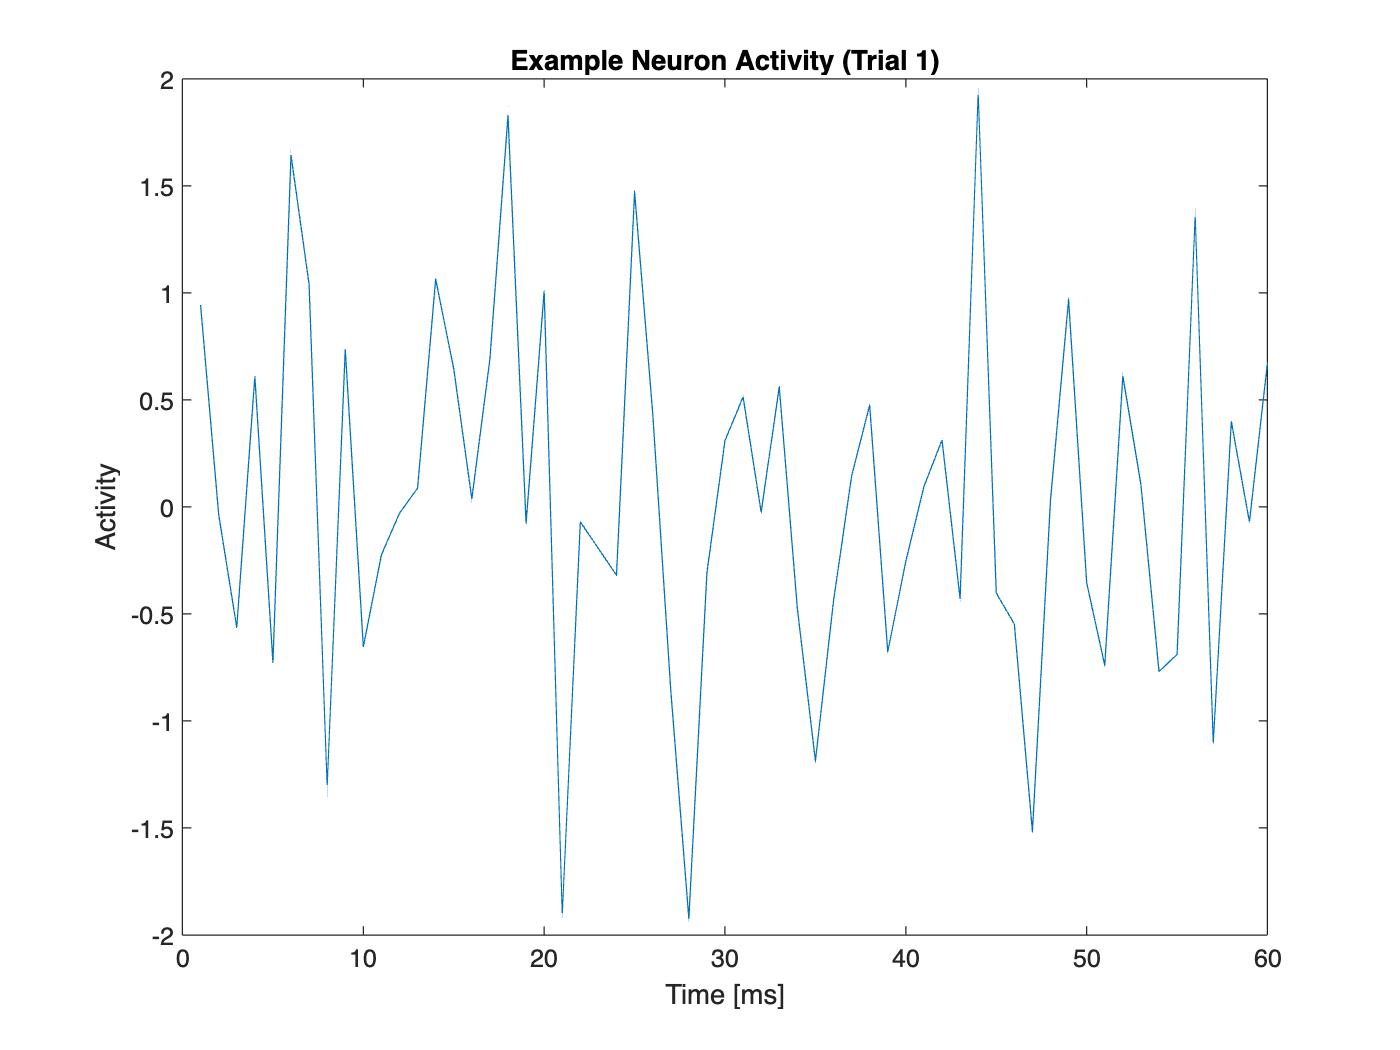

clc, clear
rng(0)
nNeurons = 20;          
nTimepoints = 60;  %ms      
nTrials = 100;  

baselineActivity = 0.2;  % Baseline activity level
noiseLevel = 0.9;        % Level of random noise in baseline activity
stimulus_amplitude = 3;  % Increase in activity for stimulus-responsive neurons

stimulus = randi([1, 2], 1, nTrials);

% Assign neurons to respond to either stimulus 1, stimulus 2, or not respond
respond_to_stimulus1 = randperm(nNeurons, floor(nNeurons / 3)); 
remaining_neurons = setdiff(1:nNeurons, respond_to_stimulus1); 
respond_to_stimulus2 = remaining_neurons(randperm(length(remaining_neurons), floor(nNeurons / 3))); 
non_responsive_neurons = setdiff(1:nNeurons, [respond_to_stimulus1, respond_to_stimulus2]);

% Create baseline neural activity (nNeurons x nTimepoints x nTrials)
neural_data = baselineActivity + noiseLevel * randn(nNeurons, nTimepoints, nTrials);

% Embed stimulus-related activity for neurons responsive to stimulus 1
for neuron = respond_to_stimulus1
    response_window_start = randi([10, 30]); % Random start of window 
    response_window_length = randi([5, 25]); % Random length of window
    response_window_end = min(response_window_start + response_window_length, nTimepoints);    
    % Increase activity during the response window in each trial where stimulus == 1
    for trial = 1:nTrials
        if stimulus(trial) == 1
            neural_data(neuron, response_window_start:response_window_end, trial) = ...
                neural_data(neuron, response_window_start:response_window_end, trial) + stimulus_amplitude;
        end
    end
end

% Embed stimulus-related activity for neurons responsive to stimulus 2
for neuron = respond_to_stimulus2
    response_window_start = randi([10, 30]); % Random start of window 
    response_window_length = randi([5, 25]); % Random length of window
    response_window_end = min(response_window_start + response_window_length, nTimepoints);    
    % Increase activity during the response window in each trial where stimulus == 2
    for trial = 1:nTrials
        if stimulus(trial) == 2
            neural_data(neuron, response_window_start:response_window_end, trial) = ...
                neural_data(neuron, response_window_start:response_window_end, trial) + stimulus_amplitude;
        end
    end
end

% Visualize example data for a single neuron across time in a single trial
figure;
plot(squeeze(neural_data(1, :, 1)));
title('Example Neuron Activity (Trial 1)');
xlabel('Time [ms]');
ylabel('Activity');

### Settings of MI to compute the Mutual Information

The `MI` function is designed to compute mutual information (MI) and related information-theoretic measures between two sets of input data, referred to as A and B. These inputs are provided as a cell array, where `inputs{1}` corresponds to the first dataset (A) and `inputs{2}` corresponds to the second dataset (B). If either A, B, or both inputs are time series, the output will also be returned as a time series.

You can specify which types of entropy calculations you would like to perform by passing a cell array of strings in the `req`O`utputs` parameter. To compute the Mutual Information of A and B, specify {`'I(A;B)'} `as output request.

The `MI` function provides an array of optional parameters that can be specified using a structure. These options allow for customization of the mutual information calculations according to the user's requirements. If these parameters are not provided, the function will default to predefined settings.

The options you can define are: 

- 'bin_method'                 : specifies the method used to bin the data                                                   (default: none)                     

- 'n_bins'                         : specifies the number of bins                                                                        (default: 3)

- 'bias'                             : specifies the bias correction method                                                            (default: naive)

- ('xtrp'/'shuff')                 : further specification for the bias correction methods 'qe' and 'shuffSub'      (default: 10 xtrp/20 shuff)

- 'supressWarnings'        : option to supress warnings e.g. for missing opts fields                                (default: false)

- 'NaN_handling'             : specify how to deal with NaN values in the data                                          (default: error)

- 'computeNulldist'          : If set to true, generates a null distribution based on the specified inputs     (default: false)

% To bin your data, you must specify both the binning method and the number of bins. You can set different methods 
% or number of bins for each input. If only one is provided, it will be applied to all inputs. 
% For more details type 'help binning' in your Command Window.
MI_opts.bin_method = {'eqpop','none'};     % Options:                                      
                                            % 'eqpop' (equal population), 
                                            % 'eqspace' (equal spacing)
                                            % 'userEdges'
                                            % 'none' (no binning)                                   
MI_opts.n_bins = {3};                       % Specify an integer for the number of bins     


% To correct for sampling bias, you can specify methods for bias correction in the MINT toolbox. If its not naive 
% you will get the naive values as the second output of the functions. 
% For more details type 'help correction' in your Command Window.
MI_opts.bias = 'qe';             % Options:                                           
                                            % 'naive' (no bias correction)                                                                       
                                            % 'qe' (Quadratic Extrapolation), 
                                            % 'le' (Linear Extrapolation), 
                                            % 'qe_shuffSub' (Quadratic with Shuffle Subtraction), 
                                            % 'le_shuffSub' (Linear with Shuffle Subtraction), 
                                            % 'shuffSub' (Shuffle Subtraction), 
                                            % 'pt' (Panzeri-Treves), 
                                            % 'bub' (BUB Correction), 
                                            % 'shuffCorr' (Shuffle Correction)

% If you use 'qe' you have to specify the number of extrapolations (opts.xtrp) the correction function should to. 
% If you use 'shuffSub' you have to specify the number of shufflings (opts.shuff) the correction function should to. 
MI_opts.shuff = 2;   
MI_opts.xtrp = 8; 
MI_opts.parallel = true;

% Several functions give you warning, e.g. if you did not specify an opts field that is needed and the function is 
% using the default it will inform you. If you don't want to get these warning you can supress them with the opts field 
% supressWarnings (default: false).
MI_opts.supressWarnings = true;

MI_opts.NaN_handling = 'removeTrial';        % Options:                                          
                                             % 'error' (Throws an error if NaN values are detected in any input)
                                             % 'removeTrial' (Removes trials (across all variables) that contain NaN values)  

### MI Outputs

The function can output three variables based on the specified settings:

- **MI_values**: This is a cell array containing the information values based on the specified reqOutputs argument. Each cell represents one requested output in the same order as specified

- **MI_naive**: This cell array contains the naive estimates. These estimates are calculated without any bias correction. It is important to note that if no bias correction is performed during the computation, the MI_values will be identical to the MI_naive values.

- **MI_nullDist**: This output contains the results of the null distribution computation, which is useful for significance testing. If the null distribution is not computed, this output will be zero.   

### How to compute the Mutual Information

#### 1. Compute the Mutual Information of each Neuron across time

If you want to compute the Mutual Information for each neuron based on the above defined settings, you can call the MI function as follows: 

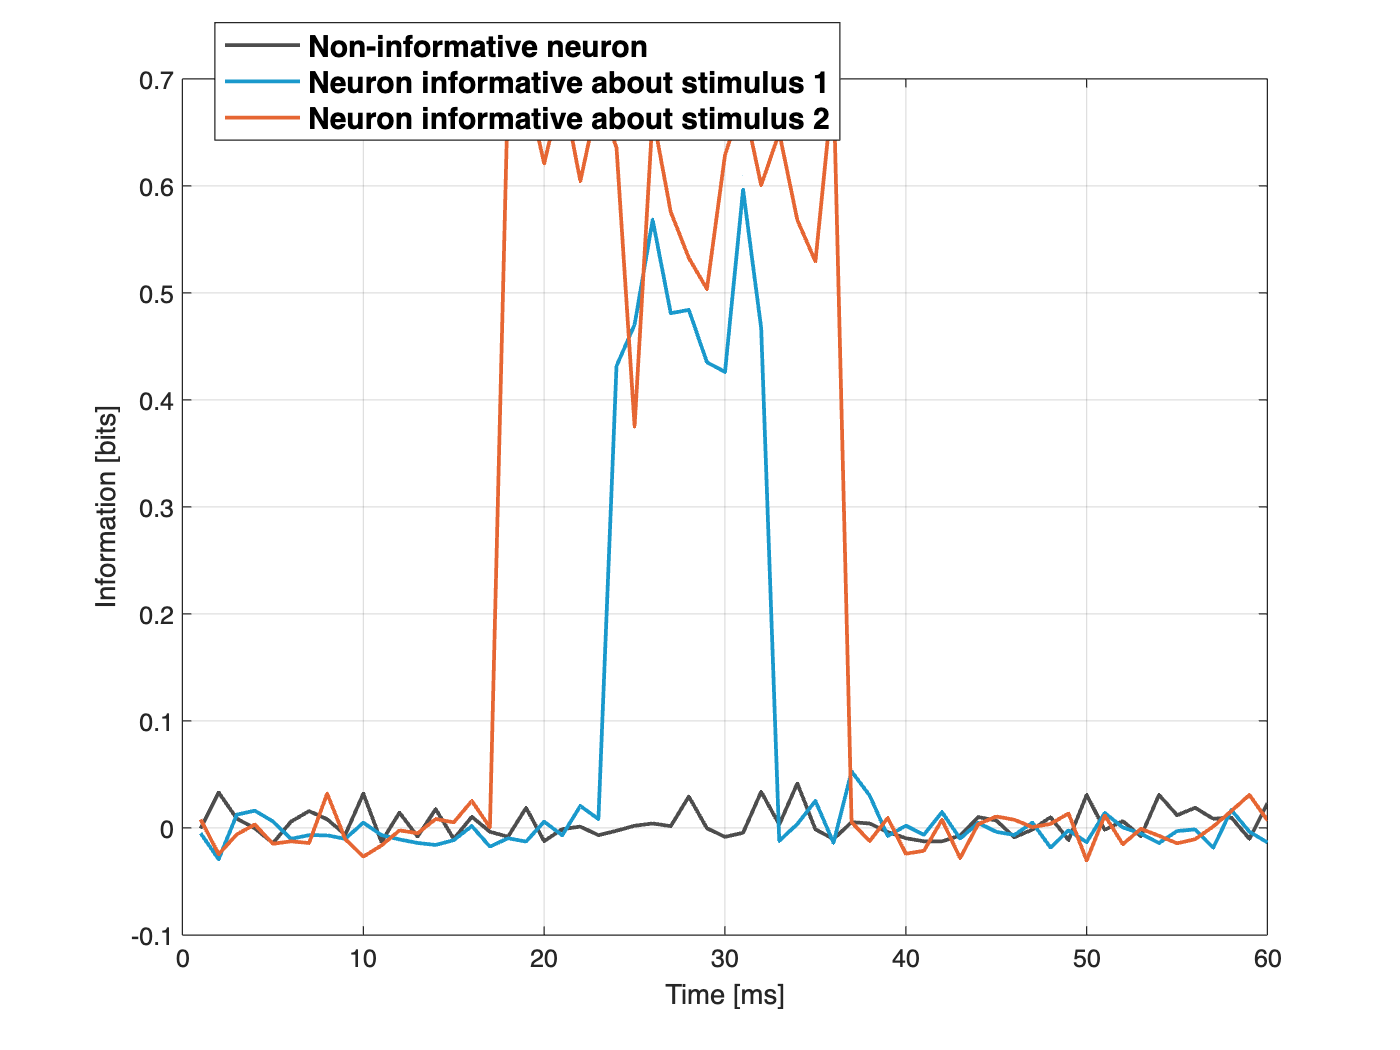

MI_singleNeuron = zeros(nNeurons, nTimepoints);
reqOutputs = {'I(A;B)'};
for neuron = 1:nNeurons
    neuron_data = neural_data(neuron,:,:);
    inputs = {neuron_data, stimulus};   
    MI_singleNeuron(neuron,:) = cell2mat(MI(inputs, reqOutputs, MI_opts));
end 

% Select example neurons for each group
non_responsive_neuron = non_responsive_neurons(1); 
responsive_neuron_1 = respond_to_stimulus1(1);     
responsive_neuron_2 = respond_to_stimulus2(1);     

time = 1:nTimepoints;
figure;
plot(time, MI_singleNeuron(non_responsive_neuron, :), 'Color', [0.3, 0.3, 0.3], 'LineWidth', 1.5); 
hold on;
plot(time, MI_singleNeuron(responsive_neuron_1, :), 'Color', [0.1, 0.6, 0.8], 'LineWidth', 1.5);   
plot(time, MI_singleNeuron(responsive_neuron_2, :), 'Color', [0.9, 0.4, 0.2], 'LineWidth', 1.5);   
hold off;

xlabel('Time [ms]');
ylabel('Information [bits]');
legend(["Non-informative neuron", "Neuron informative about stimulus 1", "Neuron informative about stimulus 2"], "FontSize", 12, "FontWeight", "bold", "Position", [0.1735 0.8668 0.4071, 0.1119])

grid on;

#### 2. Test for significance

To test for significance, you may want to generate a null distribution.The functions in the MINT toolbox offer an option to do this through the `opts.computeNulldist` parameter. To obtain the null distribution, set this option to `true` and specify the number of samples using `opts.n_samples` (default is 100). 

You can also indicate which variables should be shuffled to create the null distribution or specify if the shuffling should be conditioned on another variable using `opts.shuffling`. If you provide multiple shuffling definitions, the function will output one null distribution for each shuffling definition specified. (default: 'A' (just the firstinput variable is going to be shuffled). 

You can also specify the dimension that should be shuffled with opts.dim_shuffle. For 'Trials' it shuffles the last dimension, for 'Objects' the first and for 'Timepoints' the second.

For more information, type `help create_nullDist` in your Command Window.

To test for example for which timepoints a neuron carries significant information about the stimulus, we can first compute the null Distribution and then test for significance 

MI_opts.computeNulldist = true;  
MI_opts.parallel_sampling = true;   
MI_opts.n_samples = 100;
MI_opts.shuffling = {'A'};
MI_opts.dim_shuffle = {'Trials'};

timePointInfo = find(MI_singleNeuron(respond_to_stimulus1(1),:) > 0.4);
neuron_data = neural_data(respond_to_stimulus1(1),:,:);
inputs = {neuron_data, stimulus};   
[~, ~, MI_nullDist] = MI(inputs, reqOutputs, MI_opts);   % this can take a while, to speed up the computation you can reduce the number of samples in n_samples

MI_nullDist = cell2mat(MI_nullDist);
MI_info = MI_singleNeuron(respond_to_stimulus1(1),:);

p_values = zeros(1, nTimepoints);
for t = 1:nTimepoints
    [~, p_values(t)] = ttest(MI_nullDist(:, t), MI_info(t));         
end

#### 3. Compute the Population Information  

When analysing high-dimensional neuronal responses (such as the activity of populations of many neurons), the data space grows exponentially, making it inefficient to directly sample the joint response probabilities from the data. Therefore the MINT toolbox provides dimensionality reduction methods for the population activity. You can find the dimensionality reduction methods in the folder 'function_wrapper', including:

- glm_wrapper

- svm_wrapper

- pca_wrapepr

- nmf_wrapper

SVM_wrapper

Here you will find an example how to use the svm_wrapper. Similar to the main functions, the dimensionality reduction wrapper has three inputs. The first one is the data and for the other two, which are optional, the user can specify the requested outputs and a structure with customized options.

For the svm_wrapper these options include:

- 'svm_family'                 : Type of SVM to use, options include 'linear' and 'RBF'                                                    (default: linear)

- 'cv'                                : specifies the crossvalidation method to fit the model                                                      (default: Resubstitution (train and fit on all trials))                     

- 'libsvm'                         : specifies if the function uses libsvm or matlab functions                                                 (default: false)

- 'Standardize'                :  Boolean indicating whether to standardize features                                                       (default: true)

- 'optim_opts'                  : structure specifing options for hyperparameter optimization crossvalidation                  (default: empty struct)

- 'hp_C'                           : if no hyperparameter is specified, this parameter can define C                                       (default: 1)

- 'hp_gamma'                  : if no hyperparameter is specified, this parameter can define gamma                             (default: 1/number of Features)

The structure specifing options for hyperparameter optimization crossvalidation includes the following fields:

- 'optimization'                : set to true to perform hyperparameter optimization                                                        (default: (if optim_opts structure is not empty) true)                     

- 'optim_cv'                     : specifies the crossvalidation method for hyperparameter optimization                          (default:  Resubstitution)

- 'C_range'                     : Range of C values for hyperparameter optimization                                                       (default: [1e-3, 1e3])

- 'gamma_range'            : Range of gamma values (RBF SVM) for hyperparameter optimization                          (default: [1e-3, 1e3])

- 'parallel'                       : set to true to perform optimization in parallel                                                                   (default: false)

- 'MaxIter'                       : Maximum number of iterations for optimization                                                               (default: 50)

SVM_opts.cv = {'KFold', 3};                       % Cross-validation method:
                                                  % - 'KFold' (k-fold cross-validation, default k=5)
                                                  % - 'HoldOut' (train-test split)
                                                  % - 'LeaveMOut' (leave m out)
                                                  % - 'LeaveOut' (leave one out)
                                                  % - 'Resubstitution' (fit on entire dataset)
SVM_opts.libsvm = false;                         
                                                                                                
% If you want to perform hyperparameter optimization, you must specify a second
% structure, optim_opts, that contains the optimization parameters.
SVM_optim_opts.optimization = true;               % Set to true to perform hyperparameter optimization.

SVM_optim_opts.optim_cv = {'KFold', 2};           % Cross-validation method for hyperparameter optimization.
                                                  % Same options as in the outer loop cross-validation.

SVM_optim_opts.C_range = [1e-3, 1e3];             % Range of C values for hyperparameter optimization.

SVM_optim_opts.gamma_range = [1e-3, 1e3];         % Range of gamma values for RBF kernel for hyperparameter optimization.

SVM_optim_opts.parallel = true;                   % Whether to run optimization in parallel (default: false).

SVM_optim_opts.MaxIter = 50;                      % Maximum number of iterations for optimization (default: 50).

SVM_opts.optim_opts = SVM_optim_opts;             % Add optimization options to the SVM options.

After specifying the opts for the dimensionality reduction options, you can define the requested outputs. Options are:

- 'labels'                                        : The predicted labels for each data point.

- 'posteriorProbs'                          : The posterior probabilities for each class prediction.

- 'optimized_hyperparameters'     : The optimized hyperparameters (if hyperparameter optimization is performed).

- 'betaWeights'                              : The beta weights for the model (only for a linear SVM).

- 'intercept'                                    : The intercept term (or bias) of the model.

- 'mean_betaWeights'                   : The mean of the beta weights across all folds (only for a linear SVM).

- 'testIdx'                                       : The indices of the test set used in each fold during cross-validation.

- 'all'                                              : Outputs all outputs described above in the following order: 

{'labels', 'posteriorProbs', 'optimized_hyperparameters', 'betaWeights', 'intercept', 'mean_betaWeights', 'testIdx'}

To fit the svm we have to take the mean response over time for each neuron as the svm takes 2 dimensional data as an input:

reqOutputs = {'labels', 'mean_betaWeigths', 'intercept'};
mean_response = squeeze(mean(neural_data,2));

inputs = {mean_response, stimulus};   
SVM_out = svm_wrapper(inputs, reqOutputs, SVM_opts);

redX = SVM_out{1};
betaWeights = SVM_out{2};

After reducing the dimensionality with the svm_wrapper function, you can compute now the mutual information with the reduced response (Mutual information of predicted labels and original labels)

MI_opts.bin_method = {'none', 'none'}; % we have to adjust the bin_method, as redX is also binary now
MI_population = MI({redX, stimulus}, {'I(A;B)'}, MI_opts);

beta_weights_stimulus1 = mean(betaWeights(respond_to_stimulus1));
beta_weights_stimulus2 = mean(betaWeights(respond_to_stimulus2));
beta_weights_nonresponsive = mean(betaWeights(non_responsive_neurons));
disp(['Population information: ', num2str(MI_population{1}), ', ', ...
      'Mean Beta Weight - Stimulus 1 Responsive: ', num2str(beta_weights_stimulus1), ', ', ...
      'Mean Beta Weight - Stimulus 2 Responsive: ', num2str(beta_weights_stimulus2), ', ', ...
      'Mean Beta Weight - Non-Responsive Neurons: ', num2str(beta_weights_nonresponsive)]);

Population information: 0.86939, Mean Beta Weight - Stimulus 1 Responsive: -0.23249, Mean Beta Weight - Stimulus 2 Responsive: 0.17418, Mean Beta Weight - Non-Responsive Neurons: -0.0043206


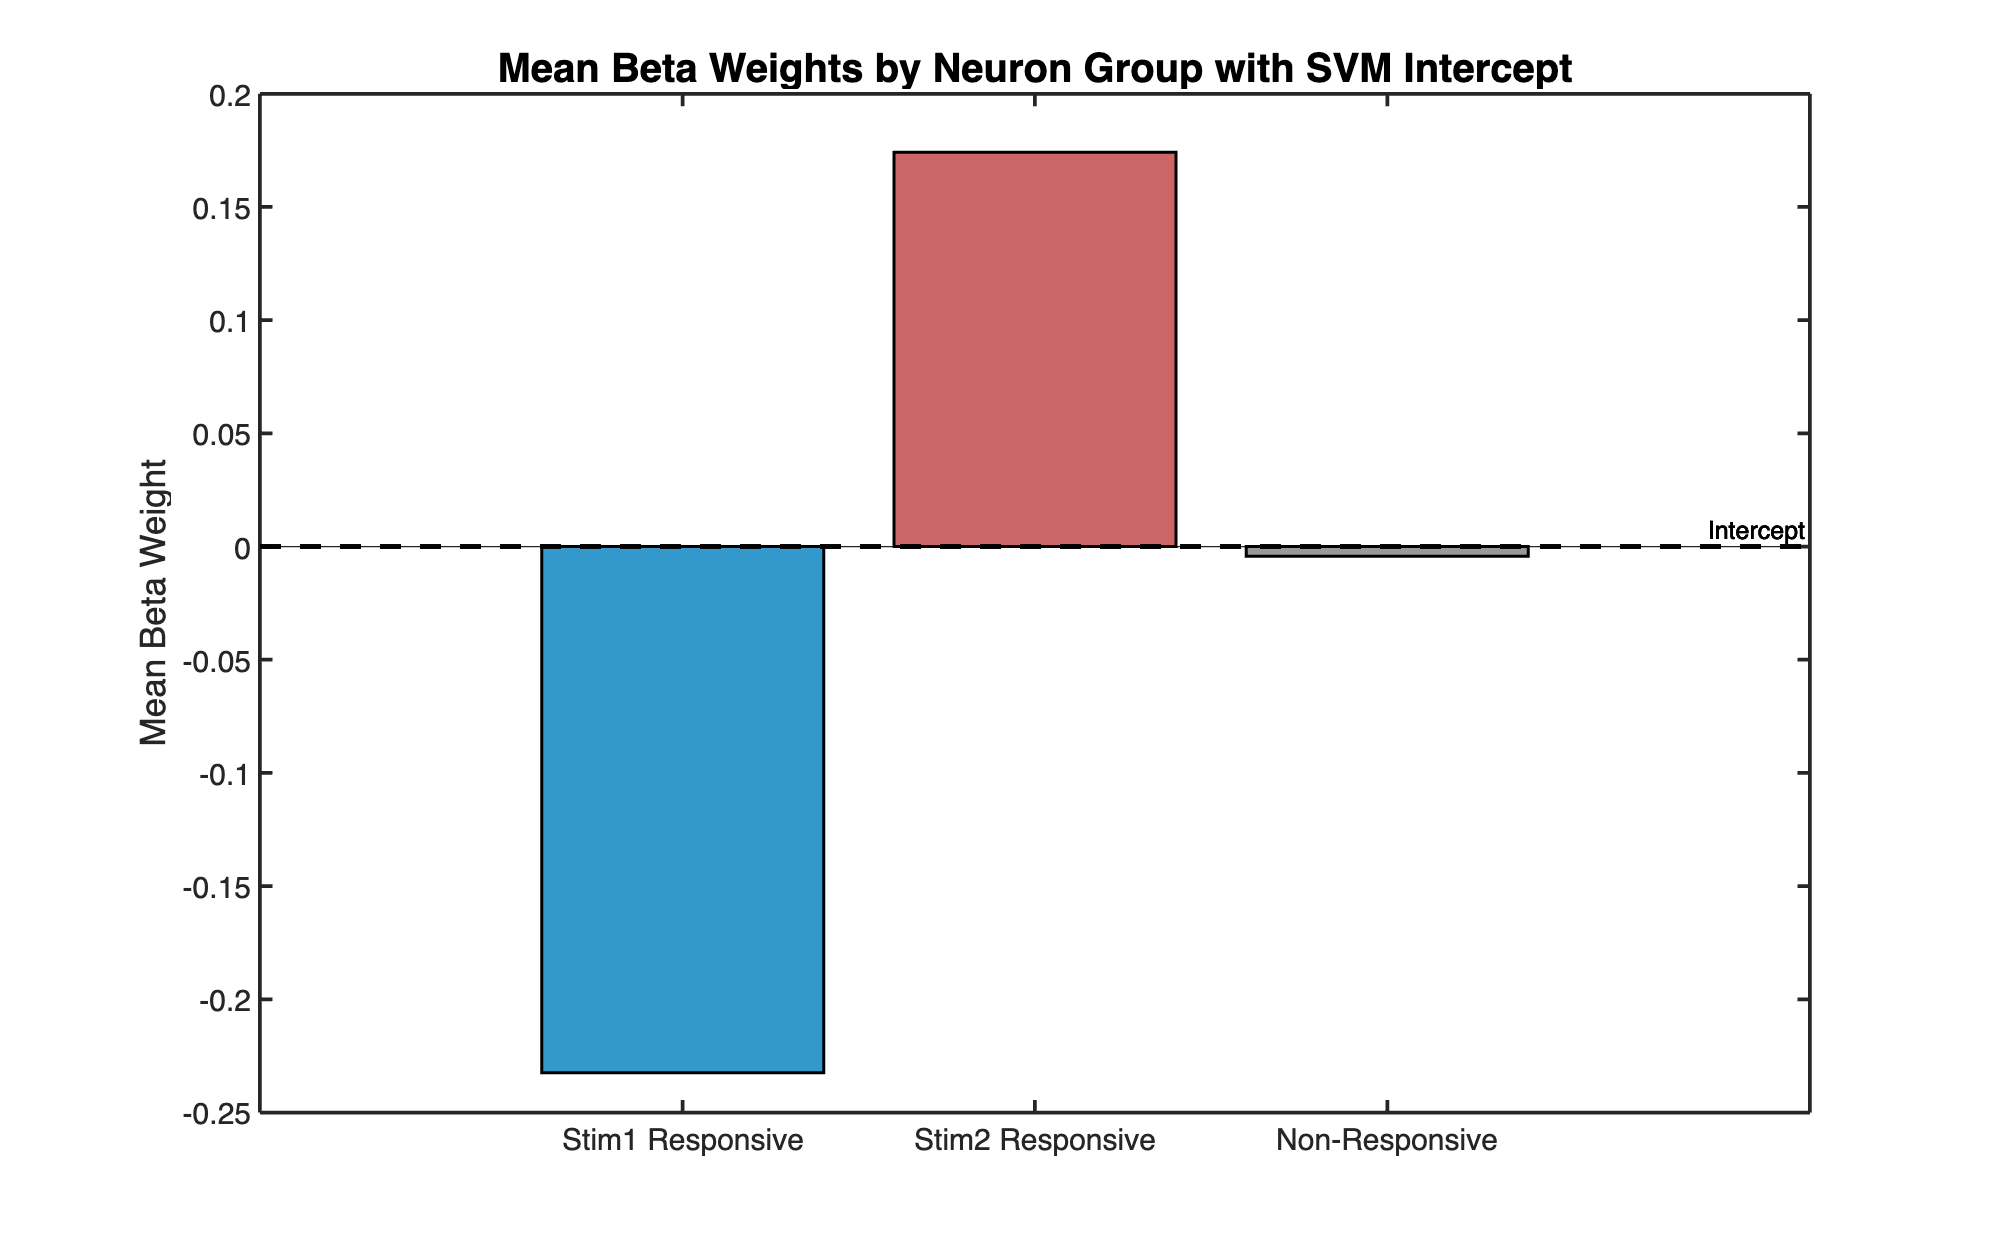



intercept = SVM_out{3}; 
beta_means = [beta_weights_stimulus1, beta_weights_stimulus2, beta_weights_nonresponsive];
group_names = {'Stim1 Responsive', 'Stim2 Responsive', 'Non-Responsive'};

% Plot
figure('Position', [100, 100, 800, 500]);  
bar(beta_means, 'FaceColor', 'flat');     
hold on;

colors = [0.2, 0.6, 0.8; 0.8, 0.4, 0.4; 0.6, 0.6, 0.6];  
for i = 1:length(beta_means)
    bar(i, beta_means(i), 'FaceColor', colors(i, :), 'EdgeColor', 'k', 'LineWidth', 1.2);
end
yline(intercept, '--k', 'LineWidth', 2, 'Label', 'Intercept');

set(gca, 'XTickLabel', group_names, 'FontSize', 12, 'LineWidth', 1.5);
ylabel('Mean Beta Weight', 'FontSize', 14);
title('Mean Beta Weights by Neuron Group with SVM Intercept', 'FontSize', 16);
hold off;